# Guião 6

## Exercicio 1

fprintf("Exercicio 1")

Exercicio 1


load Guitar03.mat;

x = x / max(abs(x)) * 0.1;              % normalização para manter valores entre -0.1 e 0.1
sound(x, fa);


## Exercicio 2 - Espetro de um sinal de uma guitarra eletrica

fprintf("Exercicio 2")

Exercicio 2

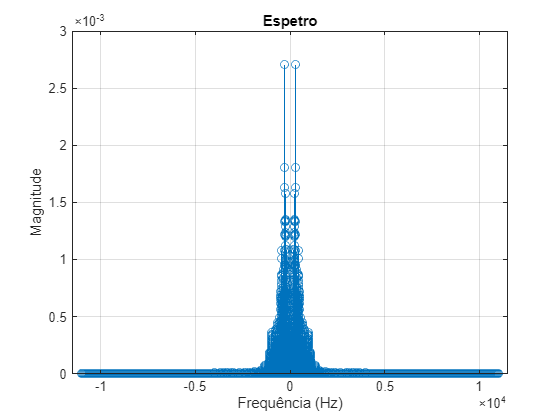


Ta = 1 / fa;                     % periodo de amostragem

[X, f] = Espetro(x, Ta);

## Exercicio 3 - Filtragem de um som

fprintf("Exercicio 3")

Exercicio 3

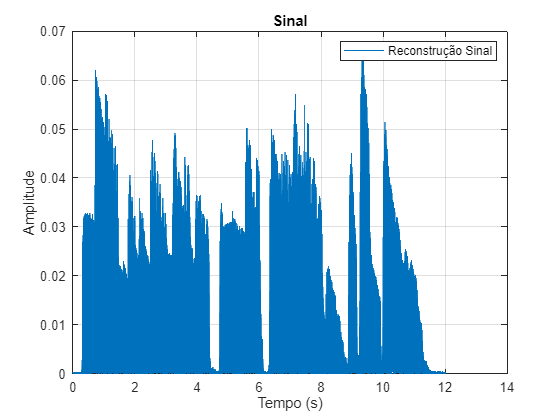


H = zeros(length(f),1);                 % filtro para os valores que estão de acordo com o dominio da frequencia
H((f>100) & (f<400)) = 1;              % definição do intervalo (devolve 1 a todos os valores que estão no intervalo)
H((f>-400) & (f<-100)) = 1;

xf = H .* X;                            % espetro filtrado - apenas as freqs no intervalo certo sao mantidas

[w,t] = Reconstroi(xf,f);


legend("Reconstrução Sinal");

sound(w,fa)

fprintf("Sinal original")

Sinal original

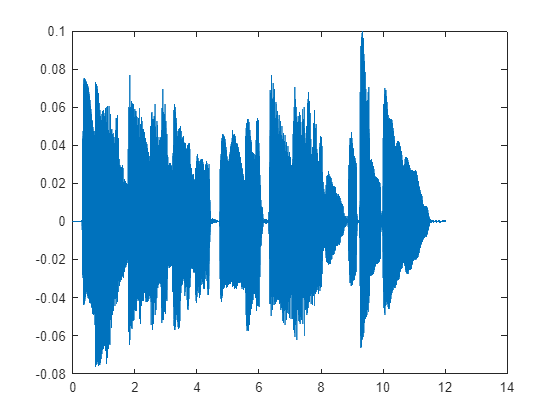

plot(t,x)

fprintf("Sinal filtrado")

Sinal filtrado

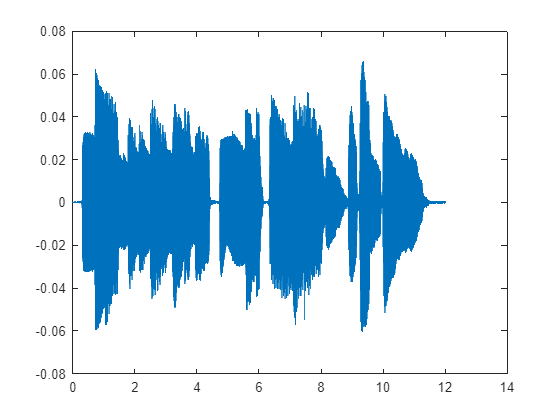

plot(t,w)

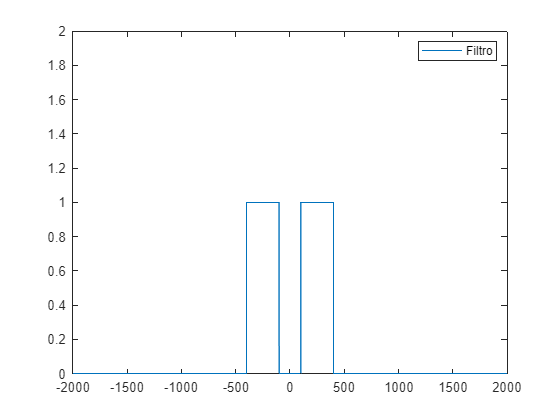


figure(2)
plot(f,H);
xlim([-2e3 2e3]);
ylim([0 2]);
legend("Filtro")

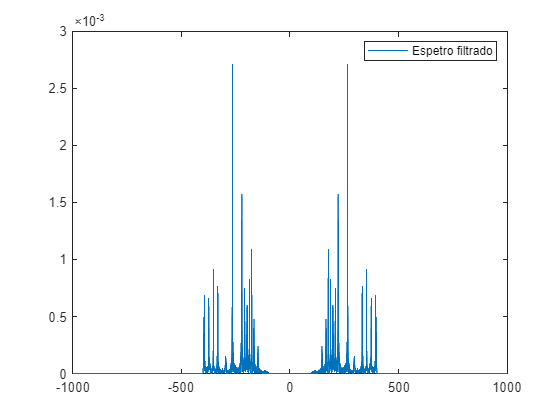


figure(3)
plot(f,abs(xf));
xlim([-1e3 1e3]);
legend("Espetro filtrado")

## II - Filtragens de sinais com ruído

## Exercicio 1

fprintf("Exercicio 1")

Exercicio 1

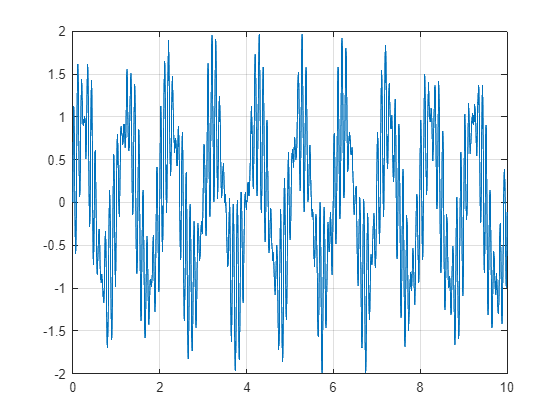


N = 10000;                          % numero de amostras
Ta = 0.001;                         % periodo de amostragem

[x,t] = GeraSinal(N,Ta);
plot(t,x)
grid on
hold on

## Exercicio 2

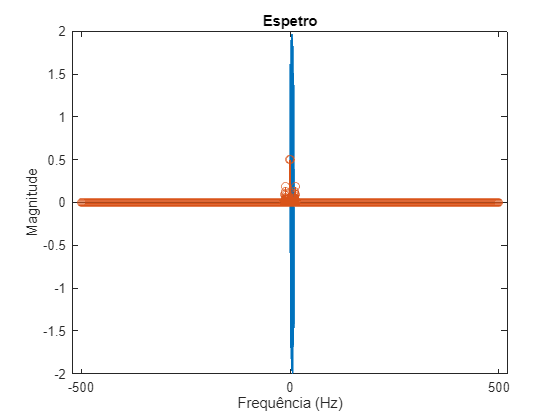

[X,f] = Espetro(x,Ta);

## Exercicio 3

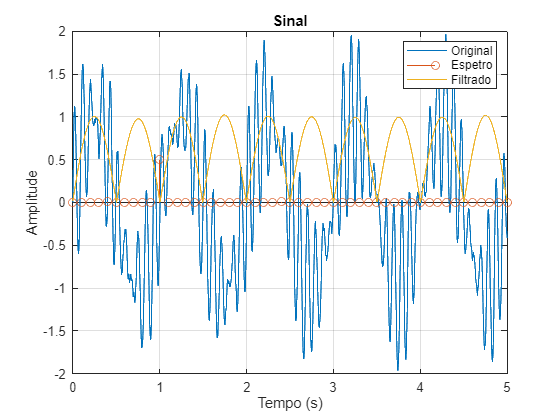

filtro = zeros(1,length(f));
filtro(abs(f)<2) = 1;
Y = filtro' .* X;

[X,T] = Reconstroi(Y,f);
legend("Original","Espetro","Filtrado")
xlim([0 5])
ylim([-2 2])

## Funções

function [X, f] = Espetro(x, Ta) 
    % Inputs:
    % x - dimensão do vetor
    % Ta - Periodo de amostragem
    %
    % Outputs:
    % X - vetor da mesma dimensão de x, com coeficientes da dft de x(t)
    % f - vetor da mesma dimensão de x, com as frequências de cada componente
    % de X
    
    Fa = 1 / Ta;                % freq de amostragem
    N = length(x);              % numero de amostras
    
    % fft(x) calcula a dft de x : devolve um
    % vetor complexo que representa amplitude e
    % as fases das componentes das freqs do sinal

    X = fftshift(fft(x))/N;         % fft(x)/N normaliza a dft, para obter amplitude media de cada componente      

    % fftshift reorganiza os valores dos vetores de X para centralizar
    % as frequências em torno de zero

    % resolução frequencia (espaçamento entre amostras de frequência)
    delta_f = Fa / N;
    
    f = (-N/2:N/2-1)*(delta_f);       % vetor de frequencias
    %  cobre o intervalo de -Fa/2 a Fa/2 em passos de delta_f.
                                
                                % abs(x) vai calcular a magnitude de cada
                                % componente
    stem(f, abs(X));            % grafico do tipo haste das magnitudes de em função das frequencias
    xlabel("Frequência (Hz)")
    ylabel("Magnitude")
    title("Espetro")
    grid;

end

function [x,t] = Reconstroi(X,f)
    %   
    %   X : vetor com os coefs da DFT de um sinal no dominio da frequencia
    %   f : vetor com as frequencias correspondentes a cada componente de X
    %
    %   x : vetor com as amostras do sinal reconstruido no dominio do tempo
    %   t : vetor de tempo associado a x

    N = length(X);                      % numero de amostras

    % ifftshift(x) descentraliza o vetor x, ou seja descloca as freqs para
    % a configuração original
    
    % ifft(ifftshift(x)) calcula a transformada inversa de fourier para retornar o sinal do dominio do tempo.
    % ifft toma o vetor de frequencia X e reconstroi o sinal temporal,
    % retorna um vetor complexo

    x = ifft(ifftshift(X))*N;     % multiplica se por N para restaurar a escala original do sinal      
 
    fa = max(f)*2;
    Ta = 1/fa;
    t = (0:N-1)*Ta;

    plot(t,abs(x));
    xlabel("Tempo (s)");
    ylabel("Amplitude");
    title("Sinal")
    grid;
end


function [x,t] = GeraSinal(N,Ta)
    %
    %   N : numero de amostras
    %   Ta : periodo de amostragem
    %       
    %   x : sinal gerado
    %   t : instantes de tempo
    %

    t = [0: (N-1)]'*Ta;                                     % vetor de tempo com N instantes

    % geração de componente estocástica

    phi = randn(N,1)*pi;                                    % gera n valores aleatorios de uma distribuiçao normal com media 0 e desvio padrao pi
    phi_i1 = zeros(N,1);                                    % vetor que armazena a integral da sequência phi usando o metodo do trapezio
    
    for n=2:N                           
        phi_i1(n) = phi_i1(n-1) + (phi(n)+phi(n-1))*Ta/2;
    end

    phi = random('normal',0,pi,N,1);
    phi_i2=zeros(N,1);

    for n=2:N
        phi_i2(n) = phi_i2(n-1) + (phi(n)+phi(n-1))*Ta/2;
    end

    x=sin(2*pi*t)+0.5*sin(2*pi*10*t + 10*phi_i1) + 0.5*sin(2*pi*12*t + 10*phi_i2);
end